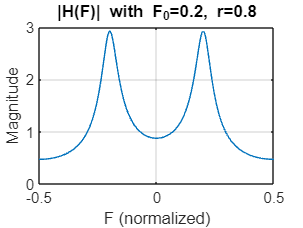

F = [-0.5:0.001:0.5];
Omega = 2*pi*F;
F0 = 0.2;       % Resonant normalized frequency
Omg0 = 2*pi*F0; % Resonant angular frequency
r = 0.8;        % Distance of poles from origin
zrs = [];       % Zeros
pls = [r*exp(j*Omg0),r*exp(-j*Omg0)]; % Poles
[mag,phs] = ss_freqz(zrs,pls,1,Omega);
plot(F,mag); grid;
xlabel('F (normalized)');
ylabel('Magnitude');
title('|H(F)| with F_{0}=0.2, r=0.8');

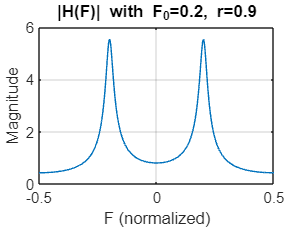

r = 0.9;
pls = [r*exp(j*Omg0),r*exp(-j*Omg0)];
[mag,phs] = ss_freqz(zrs,pls,1,Omega);
plot(F,mag); grid;
xlabel('F (normalized)');
ylabel('Magnitude');
title('|H(F)| with F_{0}=0.2, r=0.9');

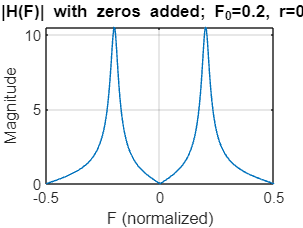

% Add two zeros at z=1 and z=-1
zrs = [-1,1];
[mag,phs] = ss_freqz(zrs,pls,1,Omega);
plot(F,mag); grid;
xlabel('F (normalized)');
ylabel('Magnitude');
title('|H(F)| with zeros added; F_{0}=0.2, r=0.9');

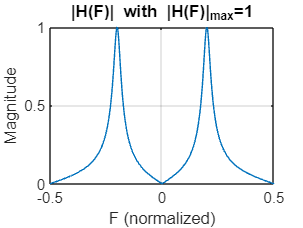

% Determine the gain factor so that the peak 
% magnitude is 1
peak = ss_freqz(zrs,pls,1,Omg0);
gain = 1/peak;
[mag,phs] = ss_freqz(zrs,pls,gain,Omega);
plot(F,mag); grid;
xlabel('F (normalized)');
ylabel('Magnitude');
title('|H(F)| with |H(F)|_{max}=1');

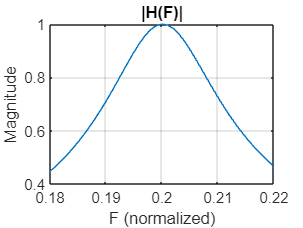

DF = 0.02;    % Normalized 3-dB bandwidth
r = 1-pi*DF;  % Compute pole radius
pls = [r*exp(j*Omg0),r*exp(-j*Omg0)]; % Poles
% Recompute F and Omg vectors to zoom in for the
% resonant frequency
F = [0.18:0.001:0.22];
Omega = 2*pi*F;
% Determine the gain factor so that the peak 
% magnitude is 1
peak = ss_freqz(zrs,pls,1,Omg0);
gain = 1/peak;
% Compute the frequency response
[mag,phs] = ss_freqz(zrs,pls,gain,Omega);
plot(F,mag); grid;
xlabel('F (normalized)');
ylabel('Magnitude');
title('|H(F)|');